 bagMsgs = rosbagreader("4.bag")

bagMsgs =   rosbagreader with properties:

           FilePath: 'C:\Users\raffa\Documents\MATLAB\Test-RL\4.bag'
          StartTime: 40.3900
            EndTime: 42.8600
        NumMessages: 4563
    AvailableTopics: [19×3 table]
    AvailableFrames: {10×1 cell}
        MessageList: [4563×4 table]



 bagSelection1 = select(bagMsgs,'Topic','/iiwa/iiwa_joint_1_effort_controller/command');
 bagSelection2 = select(bagMsgs,'Topic','/iiwa/iiwa_joint_2_effort_controller/command');
 bagSelection3 = select(bagMsgs,'Topic','/iiwa/iiwa_joint_3_effort_controller/command');
 bagSelection4 = select(bagMsgs,'Topic','/iiwa/iiwa_joint_4_effort_controller/command');
 bagSelection5 = select(bagMsgs,'Topic','/iiwa/iiwa_joint_5_effort_controller/command');
 bagSelection6 = select(bagMsgs,'Topic','/iiwa/iiwa_joint_6_effort_controller/command');
 bagSelection7 = select(bagMsgs,'Topic','/iiwa/iiwa_joint_7_effort_controller/command');
 
 
ts1 = timeseries(bagSelection1);
ts2 = timeseries(bagSelection2);
ts3 = timeseries(bagSelection3);
ts4 = timeseries(bagSelection4);
ts5 = timeseries(bagSelection5);
ts6 = timeseries(bagSelection6);
ts7 = timeseries(bagSelection7);

 

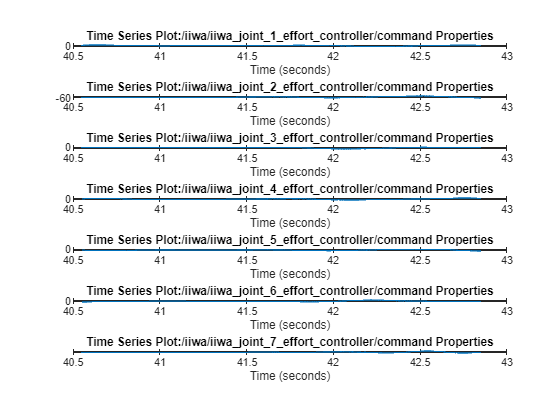


subplot(7,1,1)
plot(ts1)
grid on
subplot(7,1,2)
plot(ts2)
grid on
subplot(7,1,3)
plot(ts3)
grid on
subplot(7,1,4)
plot(ts4)
grid on
subplot(7,1,5)
plot(ts5)
grid on
subplot(7,1,6)
plot(ts6)
grid on
subplot(7,1,7)
plot(ts7)
grid on